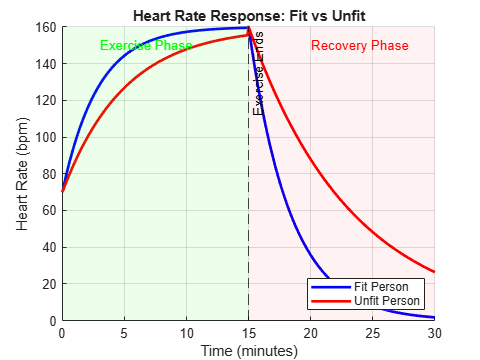

clear; clc; close all;

%% Time
t = 0:0.1:30;
t0 = 15; % end of exercise

%% Parameters
HR_rest = 70;
HR_max = 160;

% Fit vs Unfit recovery/exercise constants
k_fit_ex = 0.35;
k_fit_rec = 0.30;

k_unfit_ex = 0.20;
k_unfit_rec = 0.12;

%% Initialize
HR_fit = zeros(size(t));
HR_unfit = zeros(size(t));

%% Model Simulation
for i = 1:length(t)

    % ---------- FIT PERSON ----------
    if t(i) < t0
        HR_fit(i) = HR_rest + (HR_max - HR_rest)*(1 - exp(-k_fit_ex*t(i)));
    else
        HR_fit(i) = HR_max * exp(-k_fit_rec*(t(i) - t0));
    end

    % ---------- UNFIT PERSON ----------
    if t(i) < t0
        HR_unfit(i) = HR_rest + (HR_max - HR_rest)*(1 - exp(-k_unfit_ex*t(i)));
    else
        HR_unfit(i) = HR_max * exp(-k_unfit_rec*(t(i) - t0));
    end
end

%% ===================== PLOT 1: MAIN COMPARISON =====================
figure;
hold on;

plot(t, HR_fit, 'b', 'LineWidth', 2);
plot(t, HR_unfit, 'r', 'LineWidth', 2);

% Shade exercise and recovery regions
y = ylim;

patch([0 t0 t0 0], [y(1) y(1) y(2) y(2)], 'green', ...
    'FaceAlpha', 0.08, 'EdgeColor', 'none');

patch([t0 max(t) max(t) t0], [y(1) y(1) y(2) y(2)], 'red', ...
    'FaceAlpha', 0.05, 'EdgeColor', 'none');

xline(t0, '--k', 'Exercise Ends');

xlabel('Time (minutes)');
ylabel('Heart Rate (bpm)');
title('Heart Rate Response: Fit vs Unfit');
legend('Fit Person', 'Unfit Person', 'Location', 'southeast');
grid on;

% Annotation
text(3, 150, 'Exercise Phase', 'Color', 'green');
text(20, 150, 'Recovery Phase', 'Color', 'red');

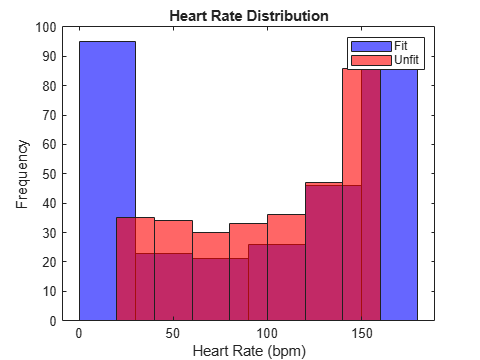


%% ===================== PLOT 2: DISTRIBUTION =====================
figure;
histogram(HR_fit, 'FaceColor', 'b'); hold on;
histogram(HR_unfit, 'FaceColor', 'r');
xlabel('Heart Rate (bpm)');
ylabel('Frequency');
title('Heart Rate Distribution');
legend('Fit', 'Unfit');

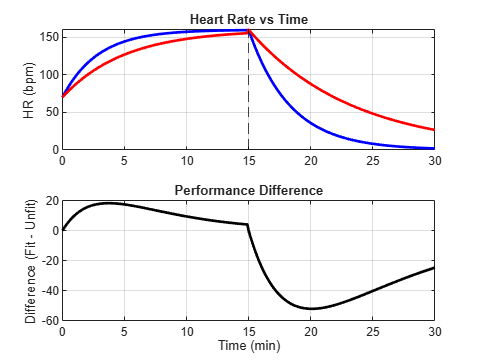


%% ===================== PLOT 3: DASHBOARD =====================
figure;

subplot(2,1,1);
plot(t, HR_fit, 'b', 'LineWidth', 2); hold on;
plot(t, HR_unfit, 'r', 'LineWidth', 2);
xline(t0, '--k');
title('Heart Rate vs Time');
ylabel('HR (bpm)');
grid on;

subplot(2,1,2);
plot(t, HR_fit - HR_unfit, 'k', 'LineWidth', 2);
xlabel('Time (min)');
ylabel('Difference (Fit - Unfit)');
title('Performance Difference');
grid on;


%% ===================== METRICS =====================
disp('--- FIT PERSON ---');

--- FIT PERSON ---


disp(['Max HR: ', num2str(max(HR_fit))]);

Max HR: 160


disp(['Avg HR: ', num2str(mean(HR_fit))]);

Avg HR: 88.8784



disp('--- UNFIT PERSON ---');

--- UNFIT PERSON ---


disp(['Max HR: ', num2str(max(HR_unfit))]);

Max HR: 160


disp(['Avg HR: ', num2str(mean(HR_unfit))]);

Avg HR: 102.6706
